# SNR effect

Another dimension that Frässle et al. vary in their simulations is the SNR. This comes into play not in the neural but the BOLD level.

Importantly, the sensitivity and specificity of the rDCM success seems to depend on the SNR (see Figures 2-4 in Frässle et al. 2018) so I wondered if the data I was generating was in a region of SNR range that was particularly bad for rDCM.

Turns out this was not something I was directly controlling in my simulations so I asked Frässle how he manipulated it and added his way to my simulations.

In this notebook I first look at how this parameter changes simulated data and then whether changing it improves model inversion.

## Effect on timeseries

How does SNR values change the generated timeseries?

stim_options = get_default_stim_options();

Code used to generate data borrowed from `make_DEM_demo_induced_fmri.m`

T  = stim_options.T;                            
TR = stim_options.TR;                             
n  = stim_options.n;                               

t  = (1:T)*TR;                       
ar_coef = stim_options.ar_coef;
u  = spm_rand_mar(T,n,ar_coef)/4;         

% experimental inputs (Cu = 0 to suppress)
% -------------------------------------------------------------------------
Cu  = ones(n, 1) * 0;
E   = cos(2*pi*TR*(1:T)/24) * 0;

% priors
% -------------------------------------------------------------------------
options.nonlinear  = stim_options.nonlinear;
options.two_state  = stim_options.two_state;
options.stochastic = stim_options.stochastic;
options.centre     = stim_options.centre;
options.induced    = stim_options.induced;

A  = stim_options.A;
B   = zeros(n,n,0);
C  = stim_options.C;
D   = zeros(n,n,0);
pP  = spm_dcm_fmri_priors(A,B,C,D,options);


% true parameters (reciprocal connectivity)
% -------------------------------------------------------------------------

if ( isfield(stim_options,'Tp') )
    pP.A = stim_options.Tp.A;
else
    pP.A = [  0  -.2    0;
             .3    0  -.1;
             0   .2    0];
end

pP.C = eye(n,n); %used by spm_int_J to create states
pP.transit = randn(n,1)/16;

% simulate response to endogenous fluctuations
%==========================================================================

% integrate states
% -------------------------------------------------------------------------
M.f  = 'spm_fx_fmri';
M.x  = sparse(n,5);
U.u  = u + (Cu*E)';
U.dt = TR;
x    = spm_int_J(pP,M,U);

% haemodynamic observer
% -------------------------------------------------------------------------
for i = 1:T
    y(i,:) = spm_gx_fmri(spm_unvec(x(i,:),M.x),[],pP)';
end

% observation noise process
% -------------------------------------------------------------------------
e    = spm_rand_mar(T,n,ar_coef)/4;

The code above first sets a bunch of parameters and then generates the variables we are interested in: the neural states x, the BOLD timeseries y and the observation noise e.

The observation noise e is an independent AR(1) process that will be added to the noiseless BOLD timeseries y. According to Frässle's response SNR determines how much of this e will be added to y in the following manner:

Using this procedure we add noise using different SNRs and plot results to see the effects on the noiseless timeseries.

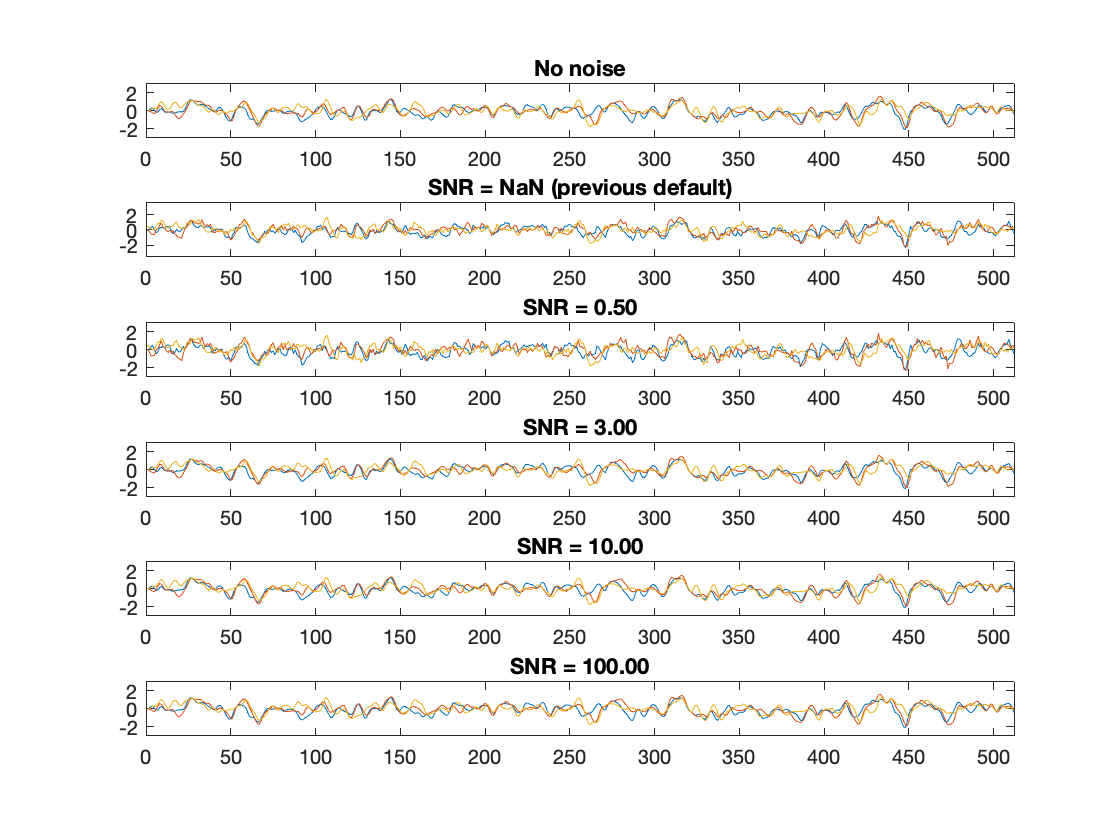

subplot(6,1,1);
plot(y);
axis([0 512 -3 3]);
title("No noise");

subplot(6,1,2);
plot(y + e);
axis([0 512 -3.5 3.5]);
title("SNR = NaN (previous default)");

SNRs = [.5 3 10 100];

for i=1:length(SNRs)
    cur_SNR = SNRs(i);
    cur_r = diag(std(y)/cur_SNR);
    cur_y = y + e*cur_r;
    subplot(6,1,i+2);
    plot(cur_y);
    axis([0 512 -3 3]);
    title(sprintf("SNR = %.02f", cur_SNR));
end

Based on these plots `SNR=3` seems like a good default in that the noisy signal frrom this SNR value looks similar to the noiseless signal.

One thing I still don't understand is how this way of using the `SNR` field translates to the definition of SNR provided in their paper: $\frac{\sigma_{\mathrm{signal}} }{\sigma_{\mathrm{noise}} }$.

SNR = 3;
r = diag(std(y)/SNR);
noise = e*r;
noisy_y = y + noise;
std(y)./std(noise)

ans =    12.2526   12.4007   11.8142


e./noise.*std(y)

ans =     3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000
    3.0000    3.0000    3.0000


## Effect on inversion

To see if my lack of control over the SNR was putting in a bad place for rDCM inversion I simulated data with the old way and the new way of SNR=3 and looked at whether the connectivity estimates improved.

Compare 12 datasets of both SNR values

clear
num_sims = 12;
type = 'r'; % setting to 'r' instead of 's' until bug is fixed
methods = 2; %1 for ridge, 2 for pruning
out_SNR3_all  = cell(1,num_sims);
out_org_all  = cell(1,num_sims);

for i = 1:num_sims
    stim_options = get_default_stim_options();
    [DCM_SNR3, opt_SNR3] = make_DEM_demo_induced_fmri(stim_options);
    [out_SNR3, opt_SNR3] = tapas_rdcm_estimate(DCM_SNR3, type, opt_SNR3, methods);
    out_SNR3_all{i} = out_SNR3;
    
    stim_options = rmfield(stim_options, 'SNR');
    [DCM_org, opt_org] = make_DEM_demo_induced_fmri(stim_options);
    [out_org, opt_org] = tapas_rdcm_estimate(DCM_org, type, opt_org, methods);
    out_org_all{i} = out_org;
end


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 5/19

Plot true connectivity, average SNR3 estimated connectivity, average SNR

cmap = mycmap();

subplot(1, 3, 1)
h = heatmap(DCM_SNR3.Tp.A);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("True A");

subplot(1, 3, 2)
cur_as = cellfun(@(c) {c.Ep.A}, out_SNR3_all(:));
mean_a = mean(cat(3, cur_as{:}), 3);
h = heatmap(mean_a);
h.CellLabelColor = 'none';
h.Colormap = cmap;
h.ColorLimits = [-0.5 0.5];
title("SNR = 3");


